# Ajuste por mínimos cuadrados

Ver Matlab Grader - Modulo de autoaprendizaje

## Ajuste Lineal

% datos
xi=[2 3 4 5 6];
yi=[1.33 1.76 2.05 2.17 2.28];

% parte 1
M=[xi' ones(5,1)];
MY=[M yi']

MY =     2.0000    1.0000    1.3300
    3.0000    1.0000    1.7600
    4.0000    1.0000    2.0500
    5.0000    1.0000    2.1700
    6.0000    1.0000    2.2800



% parte 2
A=M'*M;
B=M'*yi';
AB=[A B]

AB =    90.0000   20.0000   40.6700
   20.0000    5.0000    9.5900



% parte 3
p = A \ B

p =     0.2310
    0.9940


pendiente = p(1)

pendiente = 0.2310

intercepto = p(2)

intercepto = 0.9940


% modelo
f=@(x) pendiente*x+intercepto

f = function_handle with value:
    @(x)pendiente*x+intercepto



% Coef. determinación
ymean=sum(yi)/length(yi);
St=sum((yi-mean(yi)) .^ 2)

St = 0.5827

Sr=sum((yi-f(xi)) .^ 2)

Sr = 0.0491

r2=1-Sr/St

r2 = 0.9158

## Ajuste Cuadrático

% datos
xi=[-10 -5 4 15 20];
yi=[-30 25 80 50 -40];

% sistema sobredeterminado
M=[(xi').^2 xi' ones(5,1)];
MY=[M yi']

MY =    100   -10     1   -30
    25    -5     1    25
    16     4     1    80
   225    15     1    50
   400    20     1   -40



% ec. normales
A=M'*M;
B=M'*yi';
AB=[A B]

AB =       221506       10314         766       -5845
       10314         766          24         445
         766          24           5          85



% modelo
p = A \ B

p =    -0.5277
    5.4391
   71.7431


f=@(x) p(1)*x.^2+p(2).*x+p(3)

f = function_handle with value:
    @(x)p(1)*x.^2+p(2).*x+p(3)


xpred=[-2:2]'

xpred =     -2
    -1
     0
     1
     2


ypred=f(xpred)

ypred =    58.7540
   65.7763
   71.7431
   76.6544
   80.5103



% coef. determinación
ymean=sum(yi)/length(yi);
St=sum((yi-mean(yi)) .^ 2)

St = 10580

Sr=sum((yi-f(xi)) .^ 2)

Sr = 421.7659

r2=1-Sr/St

r2 = 0.9601


% graficando
xx = [-15:0.1:25];
figure(1);
plot(xi, yi, 'bo', 'MarkerFaceColor', 'b');
hold on;
p = polyfit(xi, yi, 1)

p =     0.0569   16.7271


yy = polyval(p, xx);
plot(xx, yy, 'r-', 'LineWidth', 2);
p = polyfit(xi, yi, 2)

p =    -0.5277    5.4391   71.7431


yy = polyval(p, xx);
plot(xx, yy, 'g--', 'LineWidth', 2);
p = polyfit(xi, yi, 4)

p =    -0.0006   -0.0015   -0.2920    5.8270   61.6017


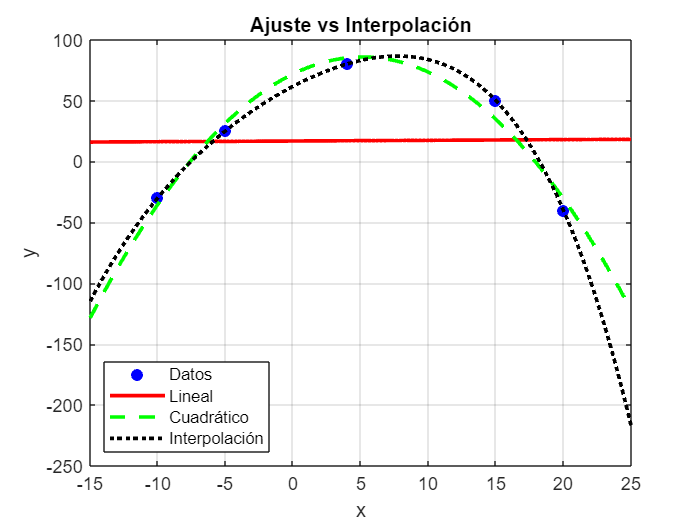

X =      2     3     4     5     6


Y =     1.3350    1.7579    2.0541    2.1748    2.2824


b = 0.2312

a = 2.7079

AB =    90.0000   20.0000   40.7281
   20.0000    5.0000    9.6041


x8 = 4.6862

w =         2114


T =    0.002972178480217


T =    0.002972200000000


w =      2.113984693889909e+03


M =   40.000000000000000  -3.824252472811867   5.866008467380269
  -3.824252472811867  20.617975855561436   1.401365539021962
   5.866008467380269   1.401365539021962  19.382024144438564


d =    0.030132673712615
   0.600389984771642
  -0.704118025104724


a =    0.010124528455099
   0.033841395102365


b =   -0.041839425727479


f = function_handle with value:
    @(t)a(1)+a(2)*cos(w*t)+b(1)*sin(w*t)


$$ans = \frac{4877059019926611\,\cos\left(\frac{4648701503744885\,x}{2199023255552}\right)}{144115188075855872}-\frac{753712088462685\,\sin\left(\frac{4648701503744885\,x}{2199023255552}\right)}{18014398509481984}+\frac{729549161242969}{72057594037927936}$$

St =    0.073862318350668


Sr =    0.023802010183955


R2 =    0.677751650429485


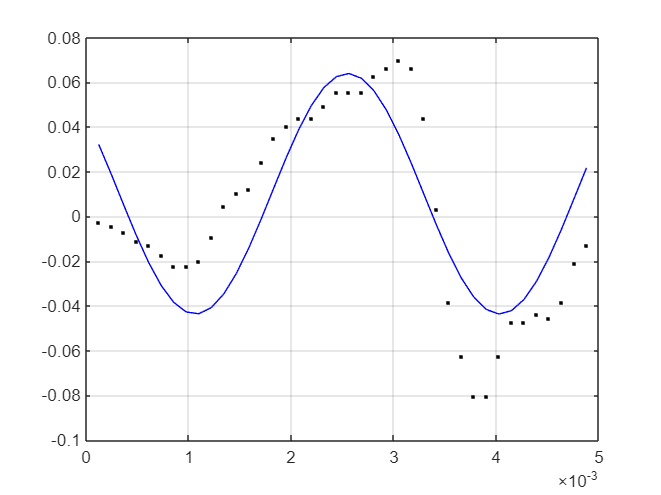

N =    168


M = 1.0e+02 *

   1.680000000000000   0.006376872642406   0.004501111707297   0.003063118633260   0.005621205835435
   0.006376872642406   0.842250555853648   0.004025259158617   0.002810602917717   0.005148069346854
   0.004501111707297   0.004025259158617   0.839151365641779   0.002084950713594   0.003787611342413
   0.003063118633260   0.002810602917717   0.002084950713594   0.837749444146352   0.002351613483789
   0.005621205835435   0.005148069346854   0.003787611342413   0.002351613483789   0.840848634358221


d = 1.0e+03 *

   1.787800000000000
   0.253221132663576
  -0.036129857118728
   0.092627096763812
   0.025950581618184


a =   10.629262055506009
   2.923552270718794
  -0.505206431098474


b =    1.057635673482177
   0.218983850641305


f = function_handle with value:
    @(t)a(1)+a(2)*cos(w*t)+a(3)*cos(2*w*t)+b(1)*sin(w*t)+b(2)*sin(2*w*t)


St =      1.963028333333334e+03


Sr =      1.122998563445101e+03


R2 =    0.427925443369334


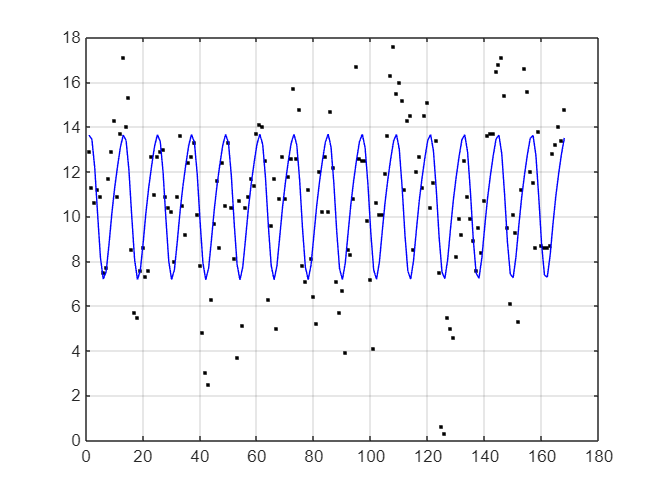

yy = polyval(p, xx);
plot(xx, yy, 'k:', 'LineWidth', 2);
xlabel('x');
ylabel('y');
title('Ajuste vs Interpolación');
legend('Datos', 'Lineal', 'Cuadrático', 'Interpolación','Location','southwest');
grid on;
hold off;